# Propulsion Function Fleeman Verification

clear; close; clc;

## Initialize variables

% unit conversions
BTU2J = 1055; % converts BTU to J
lbm2kg = convmass(1, "lbm", "kg"); % converts lbm to kg
R2K = convtemp(1, "R", "K"); % converts R to K

% Flow parameters
M_0 = 3.5; % free stream Mach number (~)
h = convlength(60E3, "ft", "m"); % altitude (m)
H_f = 17900 * BTU2J / lbm2kg; % heating value of RJ-5 fuel (J/(kg*K))
f2a = .04 % fuel-air Ratio (~)

f2a = 0.0400

gamma_0 = 1.4; % ratio of specific heats of free streem air

% Compute Combuastor Temperature
[T_0, ~, ~, ~] = atmosisa(h);

T_4 = ramjet_temperature_combustorExit(T_0, gamma_0, M_0, H_f, f2a);

T_4 / R2K % this should equal fleemans value of 3717 Rankine

ans = 3.7163e+03


% Produce Plot
M_0 = linspace(0,5);
for f2a = [.01, .03, .05, .067]
    T_4 = arrayfun(@(M) ramjet_temperature_combustorExit(T_0, gamma_0, M, H_f, f2a), M_0);
    lineName = sprintf("f/a = %g", f2a);
    plot(M_0, T_4 / R2K, "DisplayName",lineName, "LineWidth",2); hold on;
end

T_4 outside of +/- 5% error range for c_p assumption. c_p T_4 itteration not currently implemented
T_4 outside of +/- 5% error range for c_p assumption. c_p T_4 itteration not currently implemented
T_4 outside of +/- 5% error range for c_p assumption. c_p T_4 itteration not currently implemented
T_4 outside of +/- 5% error range for c_p assumption. c_p T_4 itteration not currently implemented
T_4 outside of +/- 5% error range for c_p assumption. c_p T_4 itteration not currently implemented
T_4 outside of +/- 5% error range for c_p assumption. c_p T_4 itteration not currently implemented
T_4 outside of +/- 5% error range for c_p assumption. c_p T_4 itteration not currently implemented
T_4 outside of +/- 5% error range for c_p assumption. c_p T_4 itteration not currently implemented
T_4 outside of +/- 5% error range for c_p assumption. c_p T_4 itteration not currently implemented
T_4 outside of +/- 5% error range for c_p assumption. c_p T_4 itteration not currently implemented
T_4 outsid

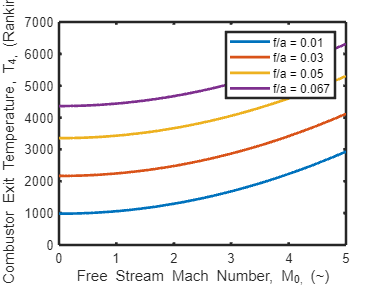

legend; xlabel("Free Stream Mach Number, M_0, (~)"); ylabel("Combustor Exit Temperature, T_4, (Rankine)");
set(gca,"LineWidth",2)